# Covid transmission with inactivation measures

#### Read CSV to get values for the US

%clearvars;
%clc;

M = csvread("US_covid_nums.csv");
[days_after_jan_22,~] = size(M);

US_confirmed = flip(M(:,1));
US_deaths = flip(M(:, 2));
US_recovered = flip(M(:, 3));

#### Define parameters



Pre_infec = 5.2;
f =1/Pre_infec;

Duration = 7;
r = 1/Duration;

R_0 = 2.2;

N = 328.2e6;
beta = R_0/(N*Duration);

eps = 38.4156/112.846;
beta = 0.5;

## Half intervention

tspan = 0:days_after_jan_22;

% half intervention
y0 = [N/2-26,25,1,0,0,0,0,N/2,0,0,0,0,0,0];

[t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);

y_sum_half = [(y(:,1)+y(:,8)) (y(:,2)+y(:,9)) (y(:,3)+y(:,10)) (y(:,4)+y(:,11)) (y(:,5)+y(:,12)) (y(:,6)+y(:,13)) (y(:,7)+y(:,14))];

% no intervention
y0 = [N-26,25,1,0,0,0,0,0,0,0,0,0,0,0];
[t,y]= ode45(@(t,y)ode_radiation(t,y,eps, beta),tspan,y0);

y_sum_no_int = [(y(:,1)+y(:,8)) (y(:,2)+y(:,9)) (y(:,3)+y(:,10)) (y(:,4)+y(:,11)) (y(:,5)+y(:,12)) (y(:,6)+y(:,13)) (y(:,7)+y(:,14))];




#### Plot results

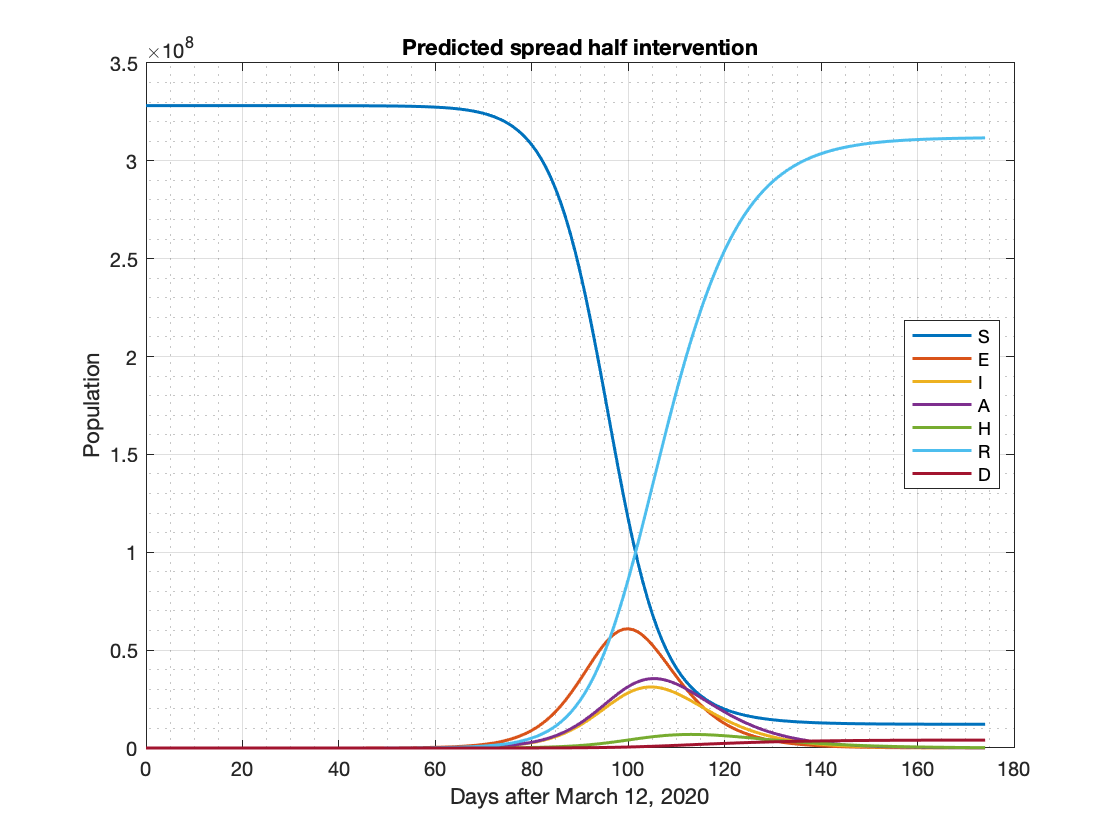

plot(t,y_sum_half,'LineWidth',1.5,'MarkerSize',18);
legend('S','E','I','A','H','R','D','Location','best')
xlabel('Days after March 12, 2020')
ylabel('Population')
title('Predicted spread half intervention')
grid on;
grid minor;

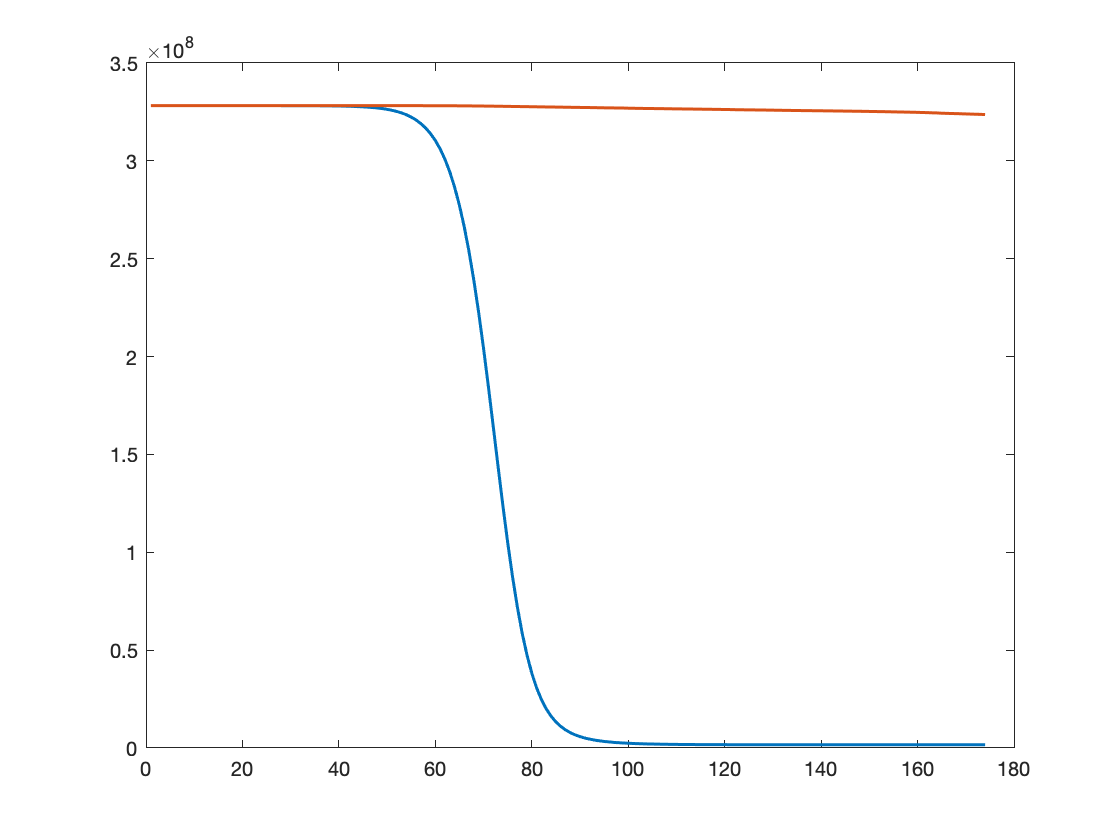


%plot of succeptible individuals vs model
US_succeptible = N.* ones(days_after_jan_22,1) - US_recovered - US_confirmed - US_deaths;
figure;
plot(1:days_after_jan_22, y_sum_no_int(1:days_after_jan_22,1),'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(1:days_after_jan_22, US_succeptible,'LineWidth', 1.5, 'MarkerSize', 18);
hold off;

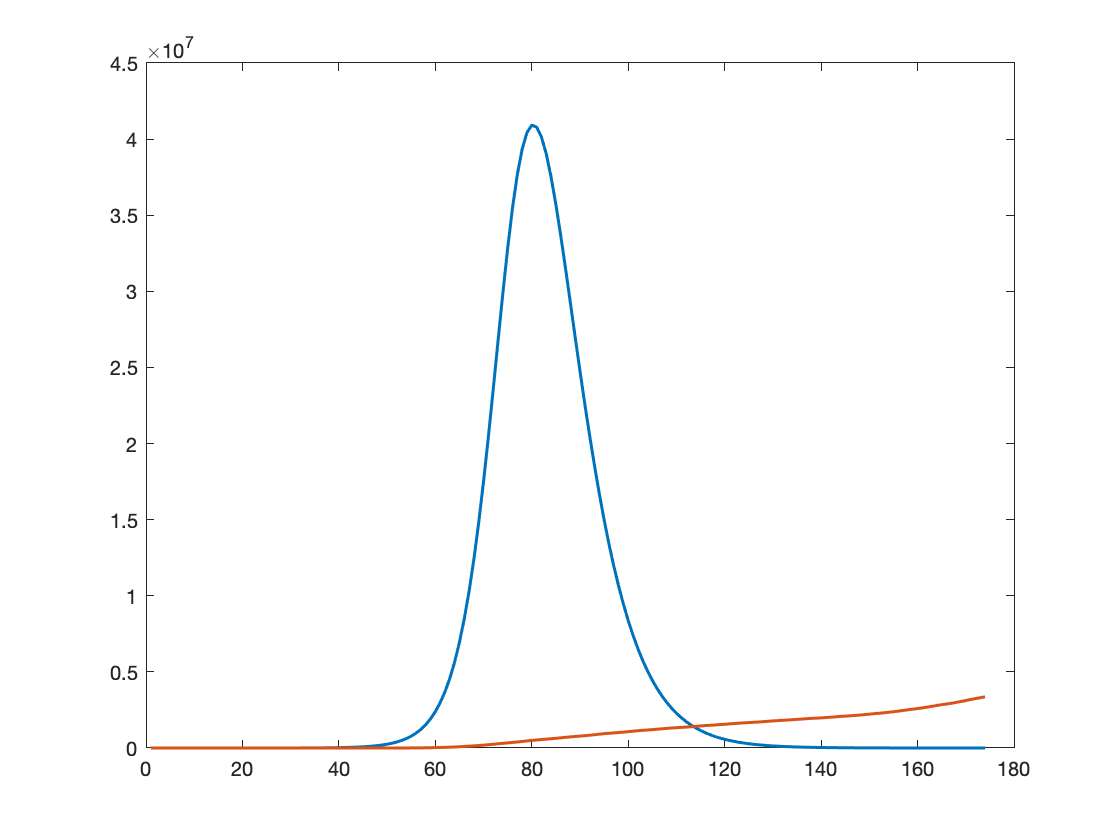


%plot of infected individuals
figure;
plot(1:days_after_jan_22, y_sum_no_int(1:days_after_jan_22,3),'LineWidth', 1.5, 'MarkerSize', 18);
hold on;
plot(1:days_after_jan_22, US_confirmed,'LineWidth', 1.5, 'MarkerSize', 18);
hold off;


%make cumulative number of infections to correspond with number confirmed
modeled_confirmed = US_confirmed;

sum = 0;
for iter = 1:days_after_jan_22
    sum = sum + modeled_confirmed(iter);
    modeled_confirmed(iter) = sum;
end

## By percent intervention

peakhospitalnum = zeros(101,1);
peakhospitalday = zeros(101,1);

totaldeaths = zeros(101,1);

for percent_rad = 0:100
    tspan = 0:1:365;
    y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];

    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp = y(:,5) + y(:,12);
    [peakhospitalnum(percent_rad+1),peakhospitalday(percent_rad+1)]=max(hosp);
    
    deaths(percent_rad + 1) = y(366,7) + y(366,14);
end


#### Plot results

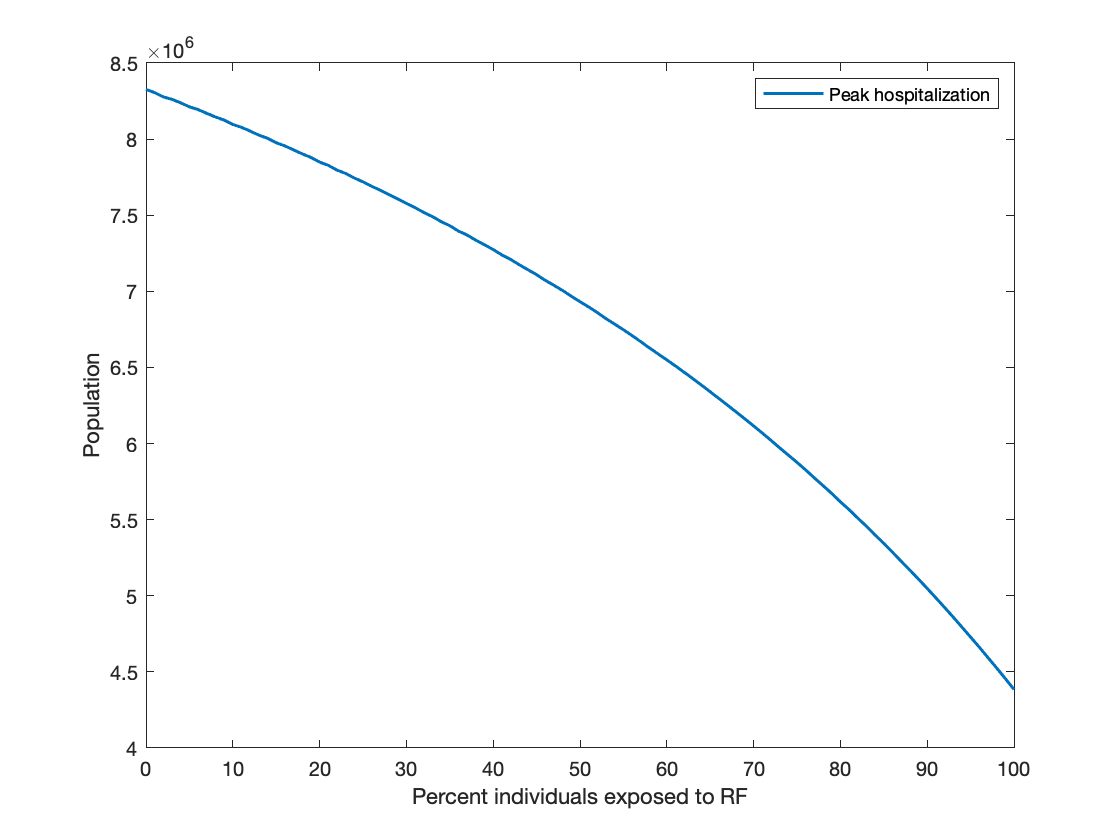

figure
plot(0:100, peakhospitalnum, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent individuals exposed to RF')
ylabel('Population')
legend('Peak hospitalization')
hold off;

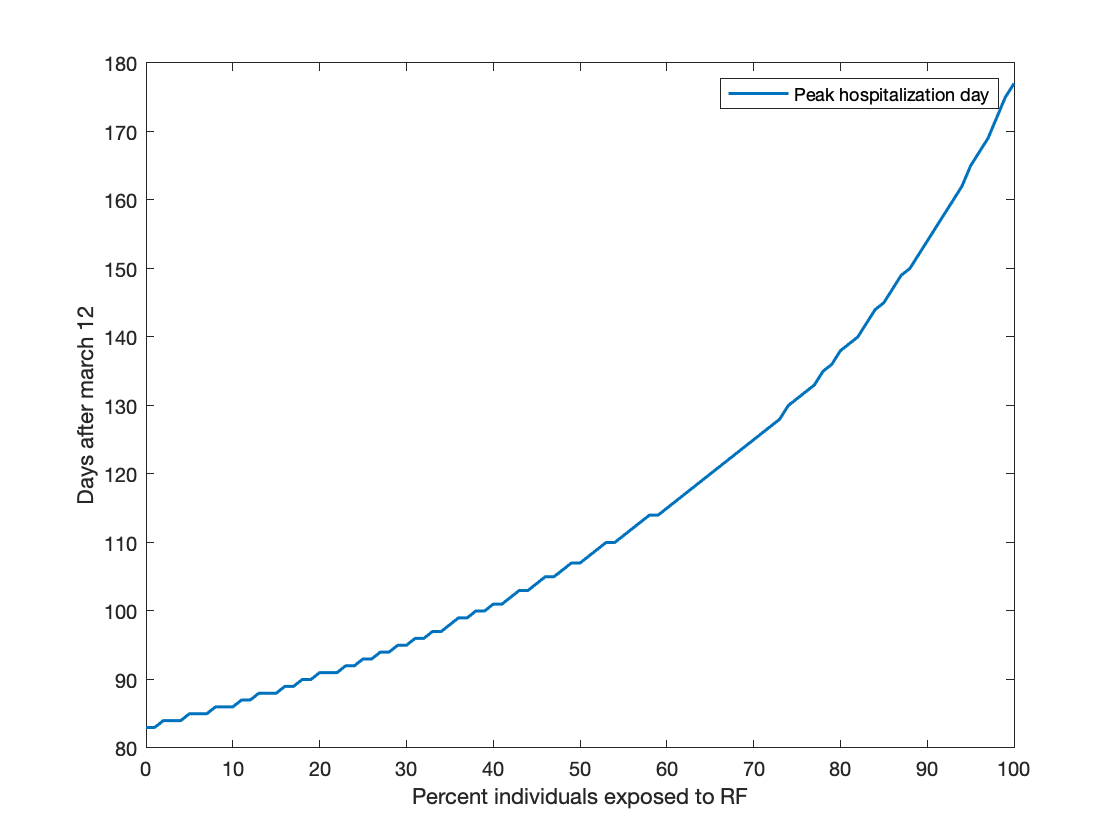


figure
plot(0:100, peakhospitalday, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent individuals exposed to RF')
ylabel('Days after march 12')
legend('Peak hospitalization day')
hold off;

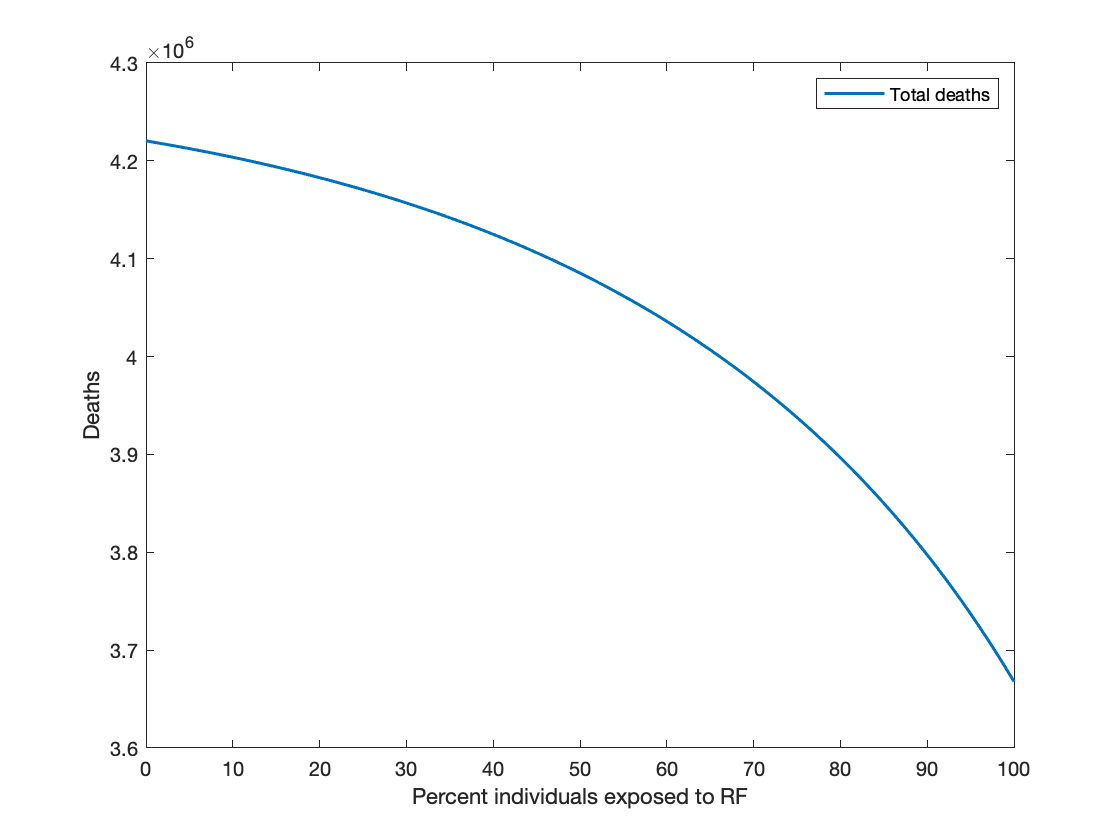


figure
plot(0:100, deaths, 'LineWidth',1.5,'MarkerSize',18);
xlabel('Percent individuals exposed to RF')
ylabel('Deaths')
legend('Total deaths')
hold off;

## Plot peak hospitalizations

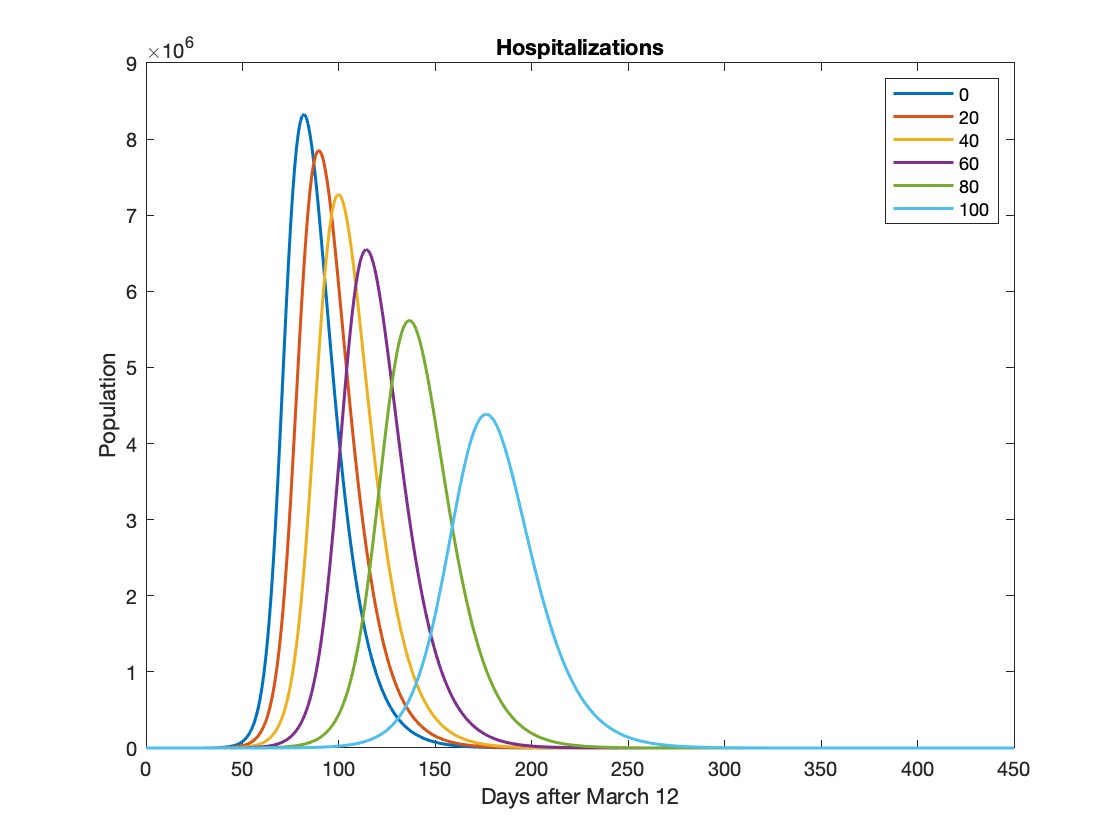

hosp = zeros(451,6);

for iter = 1:6
    percent_rad = (iter-1)*20;
    tspan = 0:1:450;
    y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];

    [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp(:,iter) = y(:,5) + y(:,12);
end

figure
plot(0:450, hosp, 'LineWidth', 1.5,  'MarkerSize', 18);
legend('0','20', '40','60','80','100')
xlabel('Days after March 12')
ylabel('Population')
title('Hospitalizations')

## Impact of varying time of inactivation

The base area under the curve is 112.846

deaths_matrix = zeros(101,25);
peakhospitalnums_matrix = zeros(101,25);
peakhospitaldays_matrix = zeros(101,25);

% for inactivation_time = 5:25
%     root = 1000/61*lambertw(61*inactivation_time/1000);
%     fun = @(x) 6.8836*exp(-.061*x)-6.8836*x/inactivation_time;
%     area = integral(fun,0,root);
%     eps = area/112.846
% end

for percent_rad = 0:100
    
    
    for inactivation_time = 1:25
        tspan = 0:1:365;
        y0 = [N*(100-percent_rad)/100-58,25,25,0,5,3,0,N*percent_rad/100,0,0,0,0,0,0];
        
        root = 1000/61*lambertw(61*inactivation_time/1000);
        fun = @(x) 6.8836*exp(-.061*x)-6.8836*x/inactivation_time;
        area = integral(fun,0,root);
        eps = area/112.846;
        
            [t,y]= ode45(@(t,y)ode_radiation(t,y,eps,beta),tspan,y0);
    
    hosp = y(:,5) + y(:,12);
    [peakhospitalnums,peakhospitaldays]=max(hosp);
    peakhospitalnums_matrix(percent_rad+1, inactivation_time) = peakhospitalnums;
    peakhospitaldays_matrix(percent_rad+1, inactivation_time) = peakhospitaldays;
    
    deaths = y(366,7) + y(366,14);
    deaths_matrix(percent_rad+1, inactivation_time) = deaths;
    
    end
    

end

%Plot data

grid off; 
colormap jet;

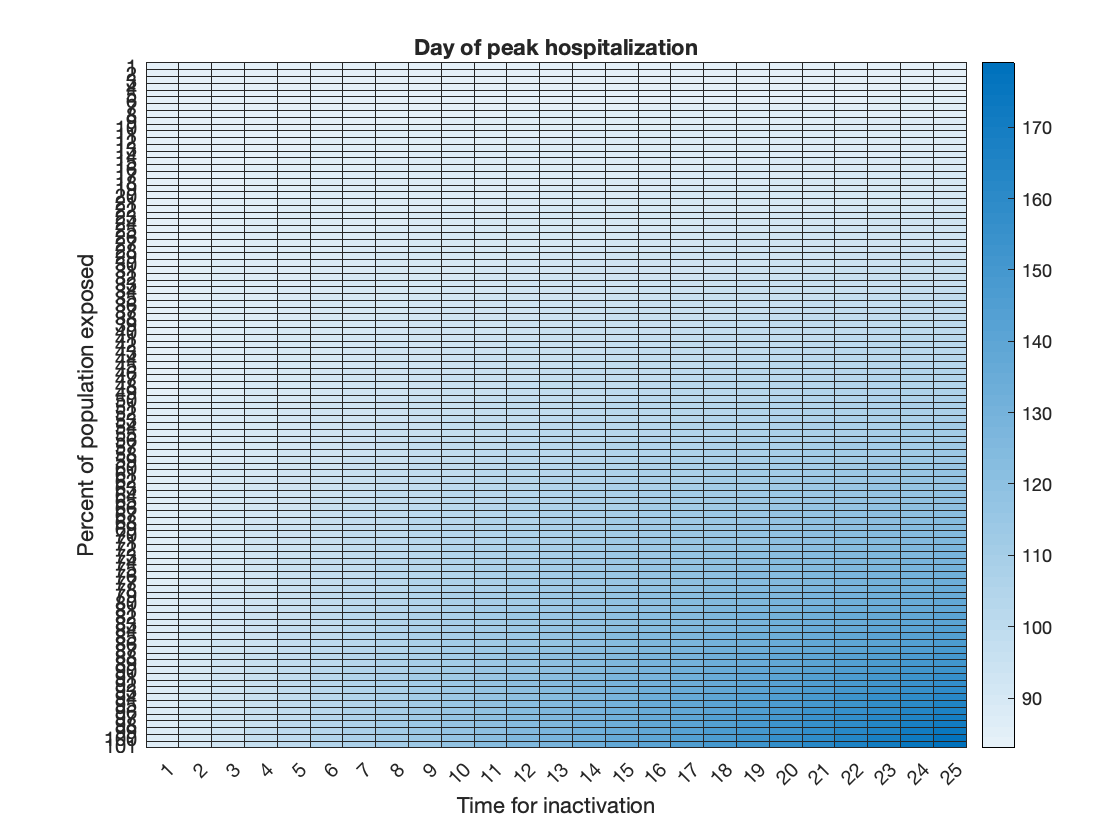


figure
heatmap(peakhospitaldays_matrix)
title( ...
    'Day of peak hospitalization')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")

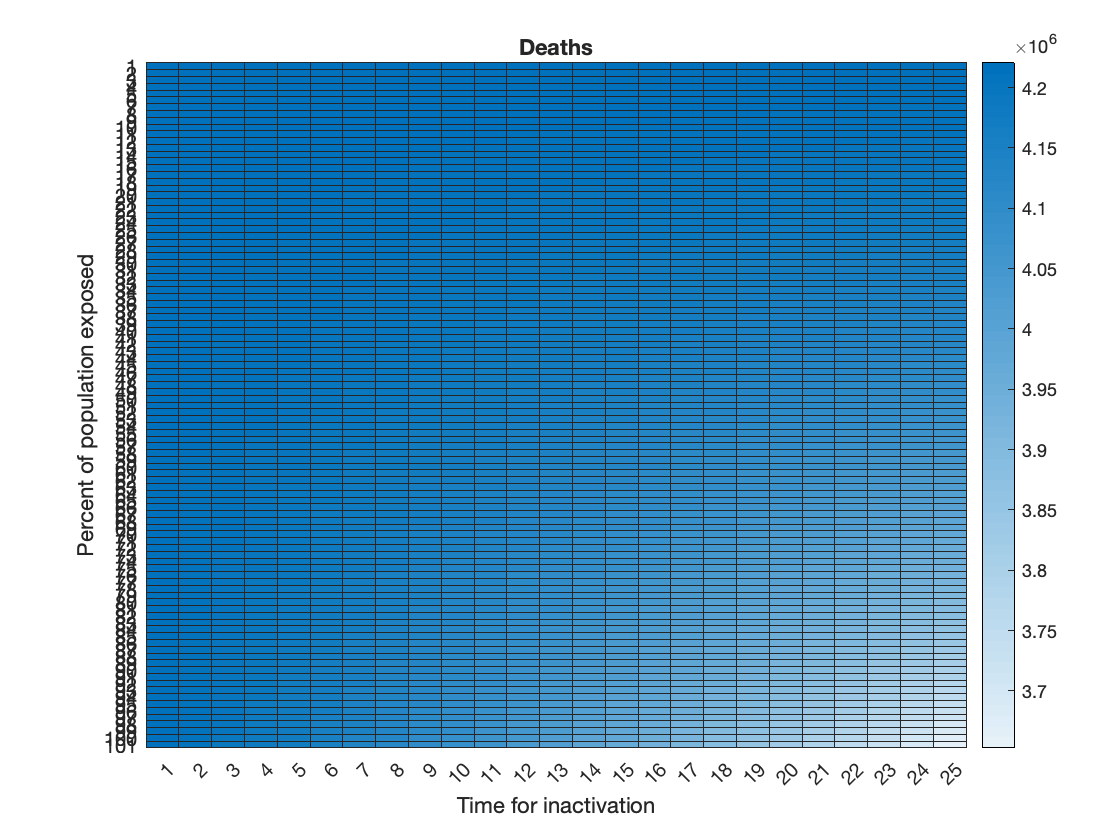


figure
grid off; 
colormap jet;
heatmap(deaths_matrix)
title('Deaths')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")

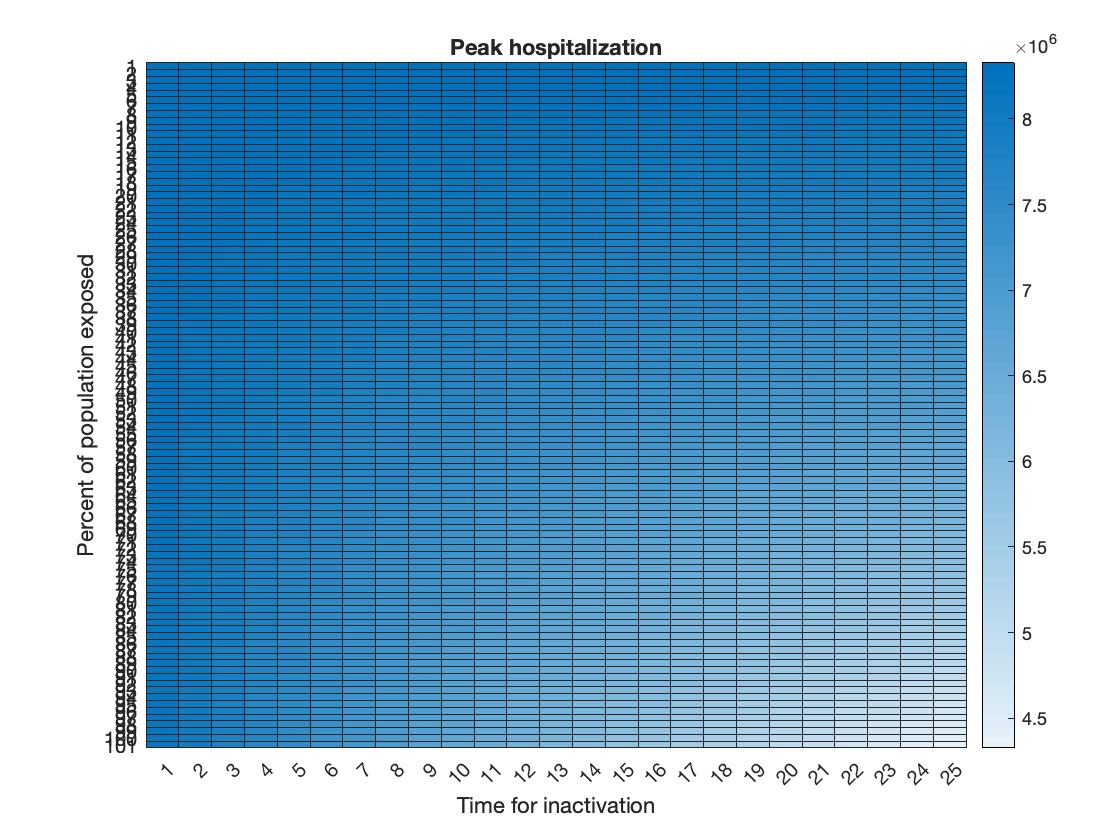


figure
grid off; 
colormap jet;
heatmap(peakhospitalnums_matrix)
title('Peak hospitalization')
xlabel("Time for inactivation")
ylabel("Percent of population exposed")